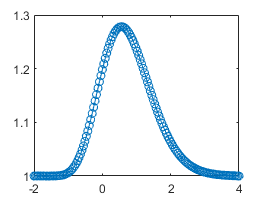

clear; clc;
N = 141; nu=1;
x = linspace(-2,4,N+1); 
dx= 0.043;
dt=0.0055; 
tf=50*dt;
M=tf/dt;
%++++++++++++++++++++++++++++++++++++++++++++++++
u = ones(N+1,1);
for i=1:N+1
	if x(i)>0.5 && x(i)<1
		u(i)=2;
    end
end
%++++++++++++++++++++++++++++++++++++++++++++++++
p=u;
q=u;

for n=1:M
	un=u;
    qn=q;
    pn=p;
    for i=2:N
		p(i)=(pn(i)+(nu*dt/dx^2)*(p(i-1)-pn(i)+pn(i+1)))/(1+nu*dt/dx^2);
    end
    for i=2:N
		q(i)=(qn(i)+(nu*dt/dx^2)*(q(i-1)-qn(i)+qn(i+1)))/(1+nu*dt/dx^2);
    end
    for i=2:N
        u(i)=0.5*(p(i)+q(i));
	%	u(i)=(un(i)+(nu*dt/dx^2)*(u(i-1)-un(i)+un(i+1)))/(1+nu*dt/dx^2);
    end
    u(N+1)=1;
    u(1)=1;
    plot(x,u,'-o')
    pause(0.2)
end